%create the figure of sound and units across the conditons

samples_aggregated = [adjustedSamples.Aluminum,adjustedSamples.Attenuated,adjustedSamples.noObject,adjustedSamples.NoWhisking];
sdf_aggregated = [referance_table.AluminumSDF{28};referance_table.AttenuatedSDF{28};referance_table.NoObjectSDF{28};referance_table.NoWhiskingSDF{28}]';

k = 6;
sdf_aggregated(2,:) = [referance_table.AluminumSDF{k};referance_table.AttenuatedSDF{k};referance_table.NoObjectSDF{k};referance_table.NoWhiskingSDF{k}]';
k = 29;
sdf_aggregated(3,:) = [referance_table.AluminumSDF{k};referance_table.AttenuatedSDF{k};referance_table.NoObjectSDF{k};referance_table.NoWhiskingSDF{k}]';
k = 17;
sdf_aggregated(4,:) = [referance_table.AluminumSDF{k};referance_table.AttenuatedSDF{k};referance_table.NoObjectSDF{k};referance_table.NoWhiskingSDF{k}]';
k = 11;
sdf_aggregated(5,:) = [referance_table.AluminumSDF{k};referance_table.AttenuatedSDF{k};referance_table.NoObjectSDF{k};referance_table.NoWhiskingSDF{k}]';
k = 2;
sdf_aggregated(6,:) = [referance_table.AluminumSDF{k};referance_table.AttenuatedSDF{k};referance_table.NoObjectSDF{k};referance_table.NoWhiskingSDF{k}]';
k = 19;
sdf_aggregated(7,:) = [referance_table.AluminumSDF{k};referance_table.AttenuatedSDF{k};referance_table.NoObjectSDF{k};referance_table.NoWhiskingSDF{k}]';
k = 22;
sdf_aggregated(8,:) = [referance_table.AluminumSDF{k};referance_table.AttenuatedSDF{k};referance_table.NoObjectSDF{k};referance_table.NoWhiskingSDF{k}]';
k = 24;
sdf_aggregated(9,:) = [referance_table.AluminumSDF{k};referance_table.AttenuatedSDF{k};referance_table.NoObjectSDF{k};referance_table.NoWhiskingSDF{k}]';
k = 25;
sdf_aggregated(10,:) = [referance_table.AluminumSDF{k};referance_table.AttenuatedSDF{k};referance_table.NoObjectSDF{k};referance_table.NoWhiskingSDF{k}]';
k = 26;
sdf_aggregated(11,:) = [referance_table.AluminumSDF{k};referance_table.AttenuatedSDF{k};referance_table.NoObjectSDF{k};referance_table.NoWhiskingSDF{k}]';



[samp_ordered,idx] = sort(samples_aggregated,'ascend');

sdf_reordered = sdf_aggregated(:,idx)

[~,startInd] = min(abs(samp_ordered - 14816000))
[~,endInd] = min(abs(samp_ordered-42280400))

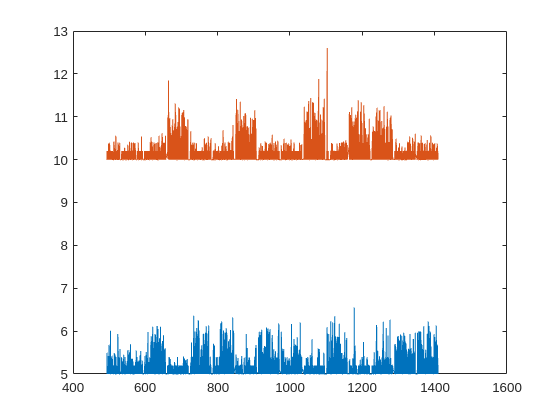

h = figure;
plot(samp_ordered(startInd:endInd)/30000,(sdf_reordered(1,startInd:endInd)/100)+4,'LineWidth',1.5)
hold on
plot(samp_ordered(startInd:endInd)/30000,(sdf_reordered(2,startInd:endInd)/100)+6,'LineWidth',1.5)
hold on


whisking = experiment.Whisking.smoothed(1:697699)

soundChanges = round(alignedTimes.alignedEphys(experiment.Conditions.all_changes))'

soundChanges =     39339895
    55088043
    70836191
    86484344
   102232491
   117830680
   133478850
   149227006
   164875534
   180623698


soundDispose(:,1) = soundChanges-3*250000;
soundDispose(:,2) = soundChanges+2*250000;

soundStart = round(experiment.timeStamp.alignedEphys(14816000))
soundEnd = round(experiment.timeStamp.alignedEphys(42280400))

soundCut = envelope(dataPascal);

soundCutMedian = median(soundCut);
for i=2:length(soundDispose)
    soundCut(soundDispose(i,1):soundDispose(i,2)) = soundCutMedian;
end

Nonfinite endpoints or increment for colon operator in index.

soundCutEnv = soundCut(soundStart:soundEnd)*10;

soundCutEnv(soundCutEnv > 1.5) = soundCutMedian*10;

plot(experiment.Cams.whisking.csv_aligned_frames/30000,whisking/50,'Color',colorBen.green,'LineWidth',1.5)
hold on;
maxY = 10

maxY = 15

plot([soundStart:soundEnd]/250000,soundCutEnv+2,'Color',colorBen.purple,'LineWidth',1.25)


most_events = max([length(experiment.conditionVector.aluminumEpochs), ...

most_events = 47

    length(experiment.conditionVector.mutedEpochs) ...
    ,length(experiment.conditionVector.nonEpochs) ...
    ,length(experiment.conditionVector.noWhiskingEpochs)])
for i = 1:most_events
    try
        startXAl = experiment.conditionVector.aluminumEpochs(i, 1)/30000;
        endXAl = experiment.conditionVector.aluminumEpochs(i, 2)/30000;
        fill([startXAl, endXAl, endXAl, startXAl], [0, 0, maxY, maxY],'r','FaceColor',colorBen.aluminum,'FaceAlpha',0.15,'EdgeColor','none');
    end
    try
        startXAt = experiment.conditionVector.mutedEpochs(i, 1)/30000;
        endXAt = experiment.conditionVector.mutedEpochs(i, 2)/30000;
        fill([startXAt, endXAt, endXAt, startXAt], [0, 0, maxY, maxY],'b','FaceColor',colorBen.muted, 'FaceAlpha', 0.15, 'EdgeColor', 'none');
    end
    try
        startXNo = experiment.conditionVector.nonEpochs(i, 1)/30000;
        endXNo = experiment.conditionVector.nonEpochs(i, 2)/30000;
        fill([startXNo, endXNo, endXNo, startXNo], [0, 0, maxY, maxY],'y','FaceColor',colorBen.non, 'FaceAlpha', 0.15, 'EdgeColor', 'none');

    end
    try
        startXNW = experiment.conditionVector.noWhiskingEpochs(i, 1)/30000;
        endXNW = experiment.conditionVector.noWhiskingEpochs(i, 2)/30000;
        fill([startXNW, endXNW, endXNW, startXNW], [0, 0, maxY, maxY],'y','FaceColor',colorBen.BrownDry, 'FaceAlpha', 0.15, 'EdgeColor', 'none');

    end
end

set(gcf,'Position',[2267,71,1058,807]);
xlim([530,1409])
ylim([0 7.5])
plot([600,600],[5 5.5],'k','LineWidth',2)
text(550,5.5,'50sp/s')
text(610,5,'0.05Pa')
plot([600 660],[1.5 1.5],'k','LineWidth',2)
text(610,1.6,'60s')
axis off;